close all; 
clc; 
clear all; 
%% Specifications 
%%%%%%%%%%%%%%%%%%%%%%%%%%%
range_res = 1; %meters
max_range = 200; %metres
vel_res = 3; %m/s
max_vel = 70; %m/s
vel = -20; %m/s
r = 110; %metres
c = 3e8; %m/s
%%%%%%%%%%%%%%%%%%%%%%%%%%%

if(abs(vel)>abs(max_vel))
    if(vel<0)
        vel = -70;   
    else 
        vel = 70;
    end
end

if(r>max_range)
    r = 200;
end


%% FMCW Waveform Generation
B = c/(2*range_res); %bandwith
Tchirp = 5.5*2*max_range/c; %chirp time based on being at least 5 to 6 times the round trip time
Slope = B/Tchirp; %slope of the chirp
L = B*Tchirp;
%Operating carrier frequency of Radar 
fc= 77e9;             %carrier freq                                                       
%The number of chirps in one sequence. Its ideal to have 2^ value for the ease of running the FFT
%for Doppler Estimation. 
Nd=128;                   % #of doppler cells OR #of sent periods % number of chirps

%The number of samples on each chirp. 
Nr=1024;                  %for length of time OR # of range cells

% Timestamp for running the displacement scenario for every sample on each
% chirp
t=linspace(0,Nd*Tchirp,Nr*Nd); %total time for samples


%Creating the vectors for Tx, Rx and Mix based on the total samples input.
Tx=zeros(1,length(t)); %transmitted sig
Rx=zeros(1,length(t)); %received signal
Mix = zeros(1,length(t)); %beat signal
%Similar vectors for range_covered and time delay.
r_t=zeros(1,length(t));
td=zeros(1,length(t));

% %% Signal generation and Moving Target simulation
% % Running the radar scenario over the time. 
tau = (r+t*vel)/c; 
Tx = cos(2*pi*(fc*t+(Slope*(t.^2))/2));
Rx = cos(2*pi*(fc*(t-tau)+(Slope*((t-tau).^2))/2));
Mix = Tx.*Rx;

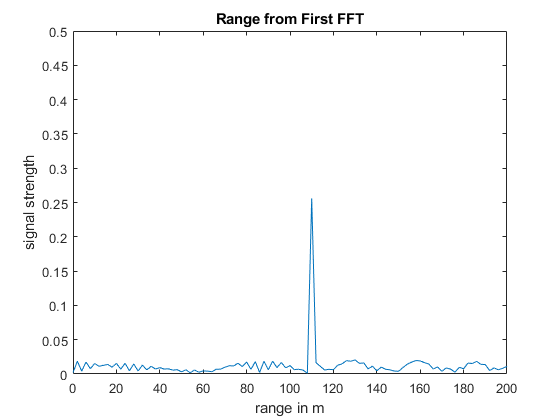

%% RANGE MEASUREMENT
Mix = reshape(Mix,[Nr,Nd]); %reshape 
signal_fft = fft(Mix)/Nr; %fft along binned along Nr Dimension 
signal_fft = abs(signal_fft);  %take absolute value and normalize the signal 
signal_fft = signal_fft(1:Nr/2); %extract one side of the axis

%plotting the fft
figure ('Name','Range from First FFT');
calculated_range = Nr/length(signal_fft)*(0:(Nr/2-1));


plot(calculated_range,signal_fft);
axis([0 200 0 0.5]);
title("Range from First FFT");
xlabel("range in m");
ylabel("signal strength");

%% RANGE DOPPLER RESPONSE
Mix=reshape(Mix,[Nr,Nd]);

% 2D FFT using the FFT size for both dimensions.
sig_fft2 = fft2(Mix,Nr,Nd);

% Taking just one side of signal from Range dimension.
sig_fft2 = sig_fft2(1:Nr/2,1:Nd);
sig_fft2 = fftshift (sig_fft2);
RDM = abs(sig_fft2);
RDM = 10*log10(RDM) ;


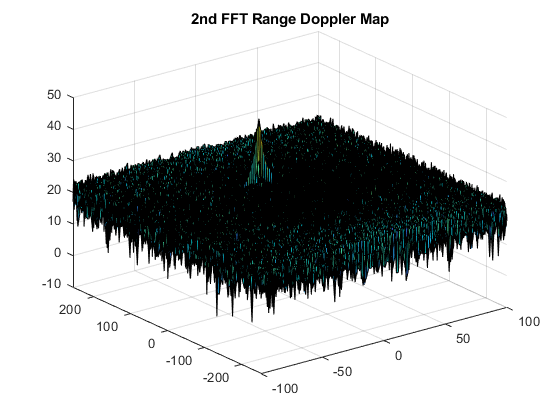

% plot the output of 2DFFT and to show axis in both
doppler_axis = linspace(-100,100,Nd);
range_axis = linspace(-200,200,Nr/2)*((Nr/2)/400);
figure,surf(doppler_axis,range_axis,RDM);
title("2nd FFT Range Doppler Map");

Tr = 14;  %range Training cells
Td = 5;  %doppler Training cells 

Gr = 4;  % range Guard cells 
Gd = 2;  % doppler Guard cells 

% Offset the threshold by SNR value in dB
offset = 17;

Guard_num = (2 * Gr + 1) * (2 * Gd + 1) - 1;  % Remove CUT
Train_num = (2 * Tr + 2 * Gr + 1) * (2 * Td + 2 * Gd + 1) - (Guard_num + 1);
cluster_mat = zeros(size(RDM));

%2D CFAR
for d = Gd+Td+1:Nd-Gd-Td %loop through doppler
    for r = Gr+Tr+1:Nr/2-Tr-Gr %loop through range 
        train = RDM(r-Gr-Tr:r+Gr+Tr,d-Gd-Td:d+Gd+Td);  %select the whole window we are using                                                                                                                                                                                                                             )                                          )
        train(r-Gr:r+Gr,d-Gd:d+Gd) = 0; %set cells that are not training cells to 0
        train = db2pow(train); %convert to linear
        train = sum(train)/Train_num; %sum and average sum over all cells
        thresh = pow2db(train)+offset ; %convert it back to db and add offset
        if(RDM(r,d)>thresh)
            cluster_mat(r,d) = 1; 
        end
    end
end

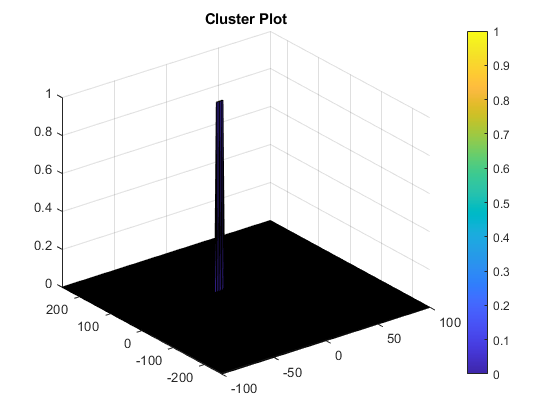

%plot the cluster
figure ('Name','Range from First FFT');
surf(doppler_axis,range_axis,cluster_mat);
title("Cluster Plot");
colorbar;